num_trials = 50; betas = [3]; lambdas = [1]; max_iter = 500;
m = 240; n = 12;

% Create parameter grid
[beta_grid, lambda_grid] = ndgrid(betas, lambdas);
parameter_combinations = [beta_grid(:), lambda_grid(:)];
num_combinations = size(parameter_combinations, 1);

% Initialize error and accuracy matrices
A_approxErrMat = zeros(num_trials, max_iter, num_combinations);
A_chebyshevErrMat = zeros(num_trials, max_iter, num_combinations);
A_accMat = zeros(num_trials, max_iter, num_combinations);

AP_approxErrMat = zeros(num_trials, max_iter, num_combinations);
AP_chebyshevErrMat = zeros(num_trials, max_iter, num_combinations);
AP_accMat = zeros(num_trials, max_iter, num_combinations);

P_approxErrMat = zeros(num_trials, max_iter, num_combinations);
P_chebyshevErrMat = zeros(num_trials, max_iter, num_combinations);
P_accMat = zeros(num_trials, max_iter, num_combinations);

for combo_idx = 1:num_combinations
    beta = parameter_combinations(combo_idx, 1);
    lambda = parameter_combinations(combo_idx, 2);

    for trial = 1:num_trials
        A = generateRandomMatrix(m, n);
        AP = CombinedSampling(A, 'gaussian_plus_pairwise');
        P = AP;
    
        [A_approxErr, A_chebyshevErr, A_acc] = HadamardSKM(A, beta, lambda, max_iter, m);
        [AP_approxErr, AP_chebyshevErr, AP_acc] = HadamardSKM(AP, beta, lambda, max_iter, m);
        [P_approxErr, P_chebyshevErr, P_acc] = HadamardSKM_only_pairwise(P, beta, lambda, max_iter, m);
    
        % Store results
        A_approxErrMat(trial, :, combo_idx) = A_approxErr;
        A_chebyshevErrMat(trial, :, combo_idx) = A_chebyshevErr;
        A_accMat(trial, :, combo_idx) = A_acc;
    
        AP_approxErrMat(trial, :, combo_idx) = AP_approxErr;
        AP_chebyshevErrMat(trial, :, combo_idx) = AP_chebyshevErr;
        AP_accMat(trial, :, combo_idx) = AP_acc;
    
        P_approxErrMat(trial, :, combo_idx) = P_approxErr;
        P_chebyshevErrMat(trial, :, combo_idx) = P_chebyshevErr;
        P_accMat(trial, :, combo_idx) = P_acc;
    end
end

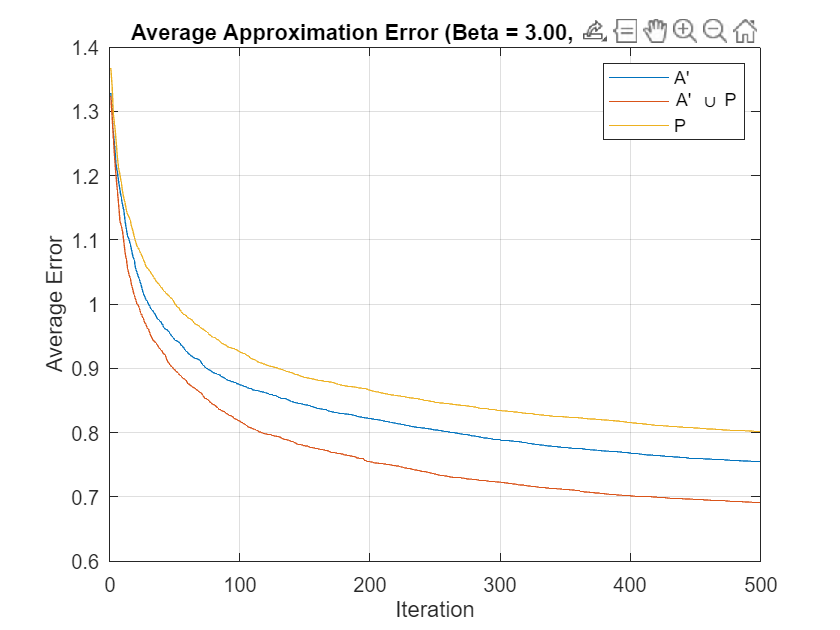

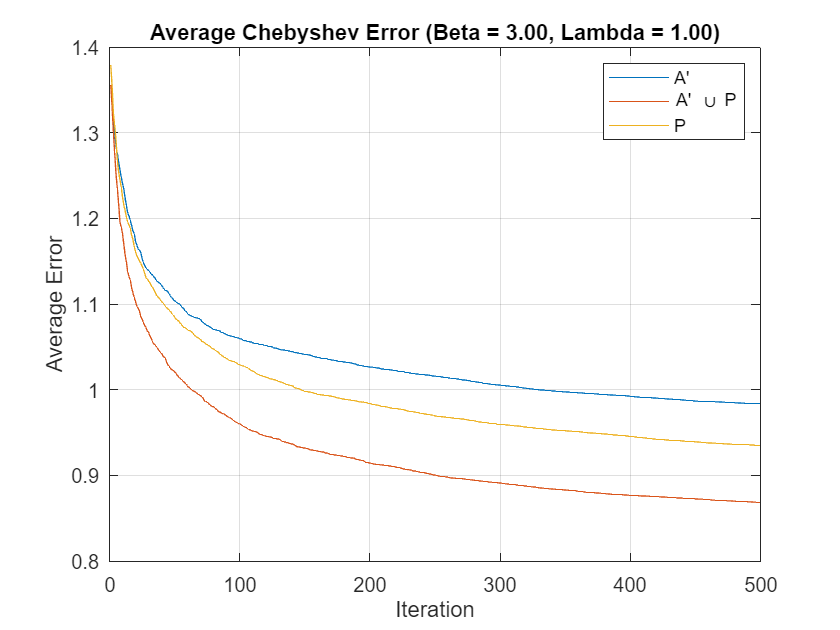

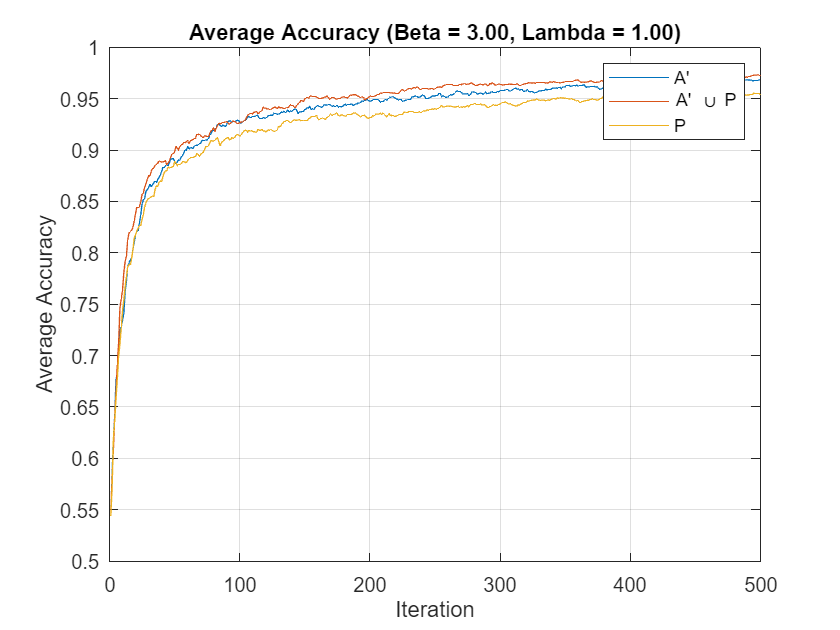

% Plotting
for combo_idx = 1:num_combinations
    beta = parameter_combinations(combo_idx, 1);
    lambda = parameter_combinations(combo_idx, 2);

    % Compute average error and accuracy over trials
    avg_A_approxErr     = mean(A_approxErrMat(:, :, combo_idx), 1);
    avg_A_chebyshevErr  = mean(A_chebyshevErrMat(:, :, combo_idx), 1);
    avg_A_acc           = mean(A_accMat(:, :, combo_idx), 1);

    avg_AP_approxErr    = mean(AP_approxErrMat(:, :, combo_idx), 1);
    avg_AP_chebyshevErr = mean(AP_chebyshevErrMat(:, :, combo_idx), 1);
    avg_AP_acc          = mean(AP_accMat(:, :, combo_idx), 1);

    avg_P_approxErr     = mean(P_approxErrMat(:, :, combo_idx), 1);
    avg_P_chebyshevErr  = mean(P_chebyshevErrMat(:, :, combo_idx), 1);
    avg_P_acc           = mean(P_accMat(:, :, combo_idx), 1);

    % Plot average error for all methods
    figure;
    plot(1:max_iter, avg_A_approxErr, 'DisplayName', "A'");
    hold on;
    plot(1:max_iter, avg_AP_approxErr, 'DisplayName', "A' \cup P");
    plot(1:max_iter, avg_P_approxErr, 'DisplayName', 'P');
    hold off;
    xlabel('Iteration');
    ylabel('Average Error');
    title(sprintf('Average Approximation Error (Beta = %.2f, Lambda = %.2f)', beta, lambda));
    legend;
    grid on;

    figure;
    plot(1:max_iter, avg_A_chebyshevErr, 'DisplayName', "A'");
    hold on;
    plot(1:max_iter, avg_AP_chebyshevErr, 'DisplayName', "A' \cup P");
    plot(1:max_iter, avg_P_chebyshevErr, 'DisplayName', 'P');
    hold off;
    xlabel('Iteration');
    ylabel('Average Error');
    title(sprintf('Average Chebyshev Error (Beta = %.2f, Lambda = %.2f)', beta, lambda));
    legend;
    grid on;

    % Plot average accuracy for all methods
    figure;
    plot(1:max_iter, avg_A_acc, 'DisplayName', "A'");
    hold on;
    plot(1:max_iter, avg_AP_acc, 'DisplayName', "A' \cup P");
    plot(1:max_iter, avg_P_acc, 'DisplayName', 'P');
    hold off;
    xlabel('Iteration');
    ylabel('Average Accuracy');
    title(sprintf('Average Accuracy (Beta = %.2f, Lambda = %.2f)', beta, lambda));
    legend;
    grid on;
end

function [A] = generateRandomMatrix(m,n)
    [U, ~] = qr(randn(m,m));
    [V, ~] = qr(randn(n,n));
    s = (1:n).^2;            % Or some desired spectrum
    S = zeros(m,n);    
    S(1:n, :) = diag(s);   

    A = U * S * V';
end

function [vec] = biSign(vec)
    vec = sign(vec);
    vec(vec == 0) = -1;
end

function mat_norm = stdMatrix(mat)
        row_norms = sqrt(sum(mat.^2, 2));
        mat_norm = mat ./ row_norms;
end

function s = sigmoid(x, lambda)
    s = 1 ./ (1 + exp(-lambda * x));
end

function [newMat] = CombinedSampling(A, type)
    valid_types = {'gaussian', 'gaussian_promax', 'gaussian_plus_pairwise'};
    if ~ismember(type, valid_types)
        error("Invalid type. Choose from 'gaussian', 'gaussian_promax', or 'gaussian_plus_pairwise'.");
    end

    [m, n] = size(A);

    if strcmp(type, 'gaussian')
        newMat = A;

    elseif strcmp(type, 'gaussian_promax')
        G = randn([nchoosek(m, 2), n]); 
        newMat = [A; G];

    elseif strcmp(type, 'gaussian_plus_pairwise')
        P = zeros(m, n);

        for i = 1:m
            b = randperm(m,2);
            P(i, :) = stdMatrix(A(b(1), :) - A(b(2), :));
        end
        
        newMat = [A; P];
    end
end

function [approxErr, chebyshevErr, acc] = HadamardSKM(A, beta, lambda, max_iter, num_original_rows)

        [m, n] = size(A);
        A = stdMatrix(A);

        xstar = unifrnd(-1,1,[n 1]); % generate solution vector
            xstar = xstar / norm(xstar); % standardize solution vector
        xk = unifrnd(-1, 1, [n 1]); % generate initial iteration vector
            xk = xk / norm(xk); % standardize initial iteration vector
        
        b = biSign(A * xstar); % extract consistent comparison vector
        B = repmat(b, [1 n]); % create array with columns b

        H = -1 * A .* B; % apply hadamard transformation
        
        cvx_begin quiet
        variables center(n) r(1)
            maximize(r)
            subject to
                H * center + r <= 0;
                r >= 0;
        cvx_end

        center = center / norm(center);

        approxErr = zeros([max_iter, 1]); chebyshevErr = zeros([max_iter, 1]); acc = zeros([max_iter, 1]); % initialize columns for result matrix

        for k = 1:max_iter
                betas = randperm(m, beta); % select random indices
                rows = H(betas,:); % index by randomly selected indices
                residuals = rows * xk; % - b' % In this case, b' is the zero vector, since we perform the hadamard transformation to scale A
                
                res_max = min(residuals(residuals > 0)); % find the greatest positive residual

                if ~isempty(res_max) && res_max(1) > 0
                        row_max = rows(residuals == res_max, :); % find the row the maximizes the residual
    
                        xk = xk - (2 - sigmoid(res_max, lambda)) * res_max * row_max(1,:)'; % update iteration vector
                        % xk = xk - lambda * res_max * row_max(1,:)'; % update iteration vector

                        xk = xk / norm(xk); % standardize iteration vector
                end
                approxErr(k) = norm(xk - xstar)';
                chebyshevErr(k) = norm(xk - center)';
                acc(k) = mean(b(1:num_original_rows) == biSign(A(1:num_original_rows,:) * xk))';
        end
end

function [approxErr, chebyshevErr, acc] = HadamardSKM_only_pairwise(A, beta, lambda, max_iter, num_original_rows)

        [m, n] = size(A);
        A = stdMatrix(A);

        xstar = unifrnd(-1,1,[n 1]); % generate solution vector
            xstar = xstar / norm(xstar); % standardize solution vector
        xk = unifrnd(-1, 1, [n 1]); % generate initial iteration vector
            xk = xk / norm(xk); % standardize initial iteration vector
        
        b = biSign(A * xstar); % extract consistent comparison vector
        B = repmat(b, [1 n]); % create array with columns b

        H = -1 * A .* B; % apply hadamard transformation
        
        cvx_begin quiet
        variables center(n) r(1)
            maximize(r)
            subject to
                H * center + r <= 0;
                r >= 0;
        cvx_end

        center = center / norm(center);

        approxErr = zeros([max_iter, 1]); chebyshevErr = zeros([max_iter, 1]); acc = zeros([max_iter, 1]); % initialize columns for result matrix

        for k = 1:max_iter
                betas = randperm(m - num_original_rows + 1, beta) + num_original_rows - 1; % select random indices
                rows = H(betas,:); % index by randomly selected indices
                residuals = rows * xk; % - b' % In this case, b' is the zero vector, since we perform the hadamard transformation to scale A
                
                res_max = min(residuals(residuals > 0)); % find the greatest positive residual

                if ~isempty(res_max) && res_max(1) > 0
                        row_max = rows(residuals == res_max, :); % find the row the maximizes the residual
    
                        xk = xk - (2 - sigmoid(res_max, lambda)) * res_max * row_max(1,:)'; % update iteration vector
                        % xk = xk - lambda * res_max * row_max(1,:)'; % update iteration vector

                        xk = xk / norm(xk); % standardize iteration vector
                end
                approxErr(k) = norm(xk - xstar)';
                chebyshevErr(k) = norm(xk - center)';
                acc(k) = mean(b(1:num_original_rows) == biSign(A(1:num_original_rows,:) * xk))';
        end
end
